close all

[O_sparse, unit_vec_sparse, ~, ~] = analyseData();

myDir = 'C:\Users\jonas\Desktop\30220 Synthesis in Earth and Space Physics Fall 22\2022_11_23_15_10_06\download';
%myDir = 'C:\Users\jonas\Desktop\30220 Synthesis in Earth and Space Physics Fall 22\2022_12_06_13_41_24\download\';

myFiles_unc = dir(fullfile(myDir,'*.unc')); %gets all unc files in struct
myFiles_unk = dir(fullfile(myDir,'*.unk'));

T_unc = struct2table(myFiles_unc); % convert the struct array to a table
T_unc_sorted = sortrows(T_unc, 'date'); % sort the table by 'DOB'
myFiles_unc = table2struct(T_unc_sorted); 

T_unk = struct2table(myFiles_unk); % convert the struct array to a table
T_unk_sorted = sortrows(T_unk, 'date'); % sort the table by 'DOB'
myFiles_unk = table2struct(T_unk_sorted);

%--------------------------------
%%
% If 70 mm is the mean, then we can 
% either go a cm up or down and see the results. 
% Positive is further away, negative is closer

%--------------------------

%Nref = sparseN70;
%Nref = sparseN(13, 1:3);
D = 105;
dist2plane = norm([0, 0, D] - O_sparse);
%on_plane = O_sparse + dist2plane.*Nref;

a = 25.5;
v = 18/180*pi;
% distance to target plane (tp) along the boresight (z-axis)
h_tp = 56; % mm

% y-coordinate
a_medium = h_tp*sin(v) + 1.60033;
h_y = a_medium/cos(v);
p1 = [0, -h_y, 0];
h_small = 1.60033/sin(v);
p2 = [0, 0, h_tp + h_small];

% Unit vec from p2 to p1 % end - start
uv_xray = (p1 - p2)./norm(p1 - p2);
h_xray = 25.5 + 1.60033/tan(v);
o_xray = h_xray*sin(v);
a_xray = h_xray*cos(v);

% x-ray location
p_xray = [0, -o_xray, p2(3) - a_xray];
h_gnd_xray = D - p2(3);
len_gnd_xray = h_gnd_xray*cos(v);

pivot_point_dist = 190 - h_small; % - norm(p_xray - p2); %%len_gnd_xray;
pivot_point = uv_xray*pivot_point_dist + p2;

%pos = -(h_xray + len_gnd_xray).*uv_xray + p_xray;
plane_dist = [+10, -10]; 
pos = -(h_xray + len_gnd_xray + plane_dist(1)).*uv_xray + p_xray;
pos2 = -(h_xray + len_gnd_xray + plane_dist(2)).*uv_xray + p_xray;
%pos3 = -(h_xray + len_gnd_xray - 7).*uv_xray + p_xray; %  + 1
pos3 = -(74.8421).*uv_xray + p_xray; %  + 1

%Nref = -uv_xray;
Nref = [0.0066, 0.3135, 0.9496];



%% 

% Draw circle
rad = 50; % 100mm = 10cm
r = 5; % radius of detectable object
%CP = drawCircle(rad,pos,Nref,'b', 2);
CP4 = drawCircle(rad,pos3,Nref,'r', 2);
CP1 = drawCircle(rad,pos,Nref,'r', 2);
CP2 = drawCircle(rad,pos2,Nref,'r', 2);
CP3 = [CP1; CP2];
k = convhull(CP3(1:end-1, 1), CP3(1:end-1, 2));
CP3 = unique(CP3(k, 1:2), 'rows');


area_total = polyarea(CP4(:, 1), CP4(:, 2));

%Step 1: Find the unweighted mean of the vertices:
cx = mean(CP3(:, 1));
cy = mean(CP3(:, 2));

%Step 2: Find the angles:
angles = atan2(CP3(:, 2) - cy, CP3(:, 1) - cx);

%Step 3: Find the correct sorted order:
[~, order] = sort(angles);

%Step 4: Reorder the coordinates:
CP3 = CP3(order, 1:2);
%%



%function analyseData()

%clearvars
close all

showImg = 0;
fig = 0;
fig_add = 0;
sparseQ = [];
sparseN = [];
sparseD = [];

hexa_file_name = 'C:\Users\jonas\Desktop\30220 Synthesis in Earth and Space Physics Fall 22\2022_11_23_15_10_06\2022_11_23_14_58_10.txt';
%hexa_file_name = 'C:\Users\jonas\Desktop\30220 Synthesis in Earth and Space Physics Fall 22\2022_12_06_13_41_24\2022_12_06_13_29_22.txt';


file = fileread(hexa_file_name);
hexa_string_all(1,:) = strfind(file,"X: ");
hexa_string_all(2,:) = strfind(file,", Y");
hexa_string_all(3,:) = strfind(file,"Y: ");
hexa_string_all(4,:) = strfind(file,", Z");
hexa_string_all(5,:) = strfind(file,"Z: ");
hexa_string_all(6,:) = strfind(file,", U");
hexa_string_all(7,:) = strfind(file,"U: ");
hexa_string_all(8,:) = strfind(file,", V");
hexa_string_all(9,:) = strfind(file,"V: ");
hexa_string_all(10,:) = strfind(file,", W");
hexa_string_all(11,:) = strfind(file,"W: ");
for i=1:size(hexa_string_all,1)
    hexa_string(i,:) = hexa_string_all(i,2:2:end);
end
hexa_string(12,:) = strfind(file,", T");
 
for j=1:size(hexa_string,2)
    for i=1:size(hexa_string,1)/2
        hexa_pos(i,j) = double(string(file(hexa_string(i*2-1,j)+3:hexa_string(i*2,j)-1)));
    end
end
hexa_pos(1,:) = hexa_pos(1,:);%*10^3;
hexa_pos(2,:) = hexa_pos(2,:);%*10^3;
hexa_pos(3,:) = hexa_pos(3,:);%*10^3;
hexa_pos(4,:) = hexa_pos(4,:);
hexa_pos(5,:) = hexa_pos(5,:);

hexa_pos

hexa_pos =          0         0    0.1713    0.1611    0.3351    0.3323    0.4909    0.6350    0.8647    1.2843    1.0643    1.4092    1.2074    1.0773    0.9241    0.7978    0.5673    0.4572    0.2145    0.1134    0.0663    0.0001   -0.0481   -0.1054   -0.1932   -0.1539   -0.2027   -0.2621   -0.1836   -0.1050   -0.0352    0.0942    0.0163
         0         0    0.1555    0.2682    0.4538    0.2699    0.3437    0.2920    0.2399    0.2161    0.0974   -0.0376   -0.2088   -0.1970   -0.2787   -0.3855   -0.3619   -0.4569   -0.4073   -0.4977   -0.2658   -0.2280   -0.1317   -0.0816   -0.1612   -0.0514   -0.0291    0.0165    0.0710    0.0819    0.1295    0.2197    0.2622
         0         0    3.8506    4.4336    5.8102    5.1227    5.9690    6.3956    7.1408    8.3819    7.7029    8.6649    8.1677    7.7850    7.3705    7.1006    6.2875    6.1768    5.2960    5.5535    4.1661    3.8255    3.0375    2.9632    4.0047    3.2581    3.6327    4.0852    3.5691    2.9632    2.9730    3.9099    4.0


hexa_pos(:,1:length(sli_files)) = hexa_pos(:,size(hexa_pos,2)-length(sli_files)+1:end)

hexa_pos =          0    0.1713    0.1611    0.3351    0.3323    0.4909    0.6350    0.8647    1.2843    1.0643    1.4092    1.2074    1.0773    0.9241    0.7978    0.5673    0.4572    0.2145    0.1134    0.0663    0.0001   -0.0481   -0.1054   -0.1932   -0.1539   -0.2027   -0.2621   -0.1836   -0.1050   -0.0352    0.0942    0.0163    0.0163
         0    0.1555    0.2682    0.4538    0.2699    0.3437    0.2920    0.2399    0.2161    0.0974   -0.0376   -0.2088   -0.1970   -0.2787   -0.3855   -0.3619   -0.4569   -0.4073   -0.4977   -0.2658   -0.2280   -0.1317   -0.0816   -0.1612   -0.0514   -0.0291    0.0165    0.0710    0.0819    0.1295    0.2197    0.2622    0.2622
         0    3.8506    4.4336    5.8102    5.1227    5.9690    6.3956    7.1408    8.3819    7.7029    8.6649    8.1677    7.7850    7.3705    7.1006    6.2875    6.1768    5.2960    5.5535    4.1661    3.8255    3.0375    2.9632    4.0047    3.2581    3.6327    4.0852    3.5691    2.9632    2.9730    3.9099    4.0853    4.0


% rot = [...
%     2.40414, 2.1858, 0, 0.171232, 0.155689, 3.85059; ... % 1
%     1.94515, 3.2397, 0, 0.161108, 0.268239, 4.43356; ... % 2
%     3.01279, 4.08562, 0, 0.33504, 0.454169, 5.81019; ... % 3
%     3.42935, 2.78748, 0, 0.332027, 0.269936, 5.12272; ... % 4
%     4.28382, 3.00152, 0, 0.49061, 0.343917, 5.96885; ... % 5
%     5.13638, 2.35917, 0, 0.635159, 0.292041, 6.39556; ... % 6
%     6.17589, 1.70981, 0, 0.86476, 0.23984, 7.14082; ... % 7
%     7.62254, 1.27776, 0, 1.28462, 0.215959, 8.38191; ... % 8
%     6.96826, 0.636594, 0, 1.06416, 0.0974557, 7.70294; ... % 9
%     8.04063, -0.212994, 0, 1.40918, -0.0374517, 8.66489; ... % 10
%     7.38604, -1.27303, 0, 1.20752, -0.208684, 8.16768; ... % 11
%     6.96826, -1.27303, 0, 1.07735, -0.19729, 7.78499; ... % 12
%     6.36357, -1.91624, 0, 0.923885, -0.278728, 7.37051; ... % 13
%     5.73168, -2.76679, 0, 0.797612, -0.385515, 7.10062; ... % 14
%     4.67549, -2.97925, 0, 0.567359, -0.361763, 6.28754; ... % 15
%     3.84245, -3.84245, 0, 0.457265, -0.457265, 6.17684; ... % 16
%     2.13691, -4.05523, 0, 0.214631, -0.407062, 5.29595; ... % 17
%     1.07283, -4.71036, 0, 0.113543, -0.497991, 5.55351; ... % 18
%     0.8583, -3.42935, 0, 0.0665075, -0.265583, 4.16609; ... % 19
%     -3.22755, -3.22755, 0, 0, -0.22823, 3.82548; ... % 20
%     -0.864776, -2.37695, 0, -0.0479596, -0.13179, 3.03744; ... % 21
%     -1.94515, -1.51312, 0, -0.105097, -0.081761, 2.96316; ... % 22
%     -2.60256, -2.16926, 0, -0.193268, -0.161108, 4.00468; ... % 23
%    -2.58302, -0.861526, 0, -0.154158, -0.0514325, 3.25814; ... % 24
%     -3.02414, -0.432413, 0, -0.202435, -0.0289588, 3.63265; ... % 25
%     -3.45517, 0.216209, 0, -0.262029, 0.0164065, 4.08522; ... % 26
%     -2.79794, 1.07686, 0, -0.183838, 0.0707786, 3.5691; ... % 27
%     -1.94515, 1.51312, 0, -0.105097, 0.081761, 2.96316; ... % 28
%     -0.65106, 2.38594, 0, -0.0353051, 0.129348, 2.97297; ... % 29
%    1.30195, 3.03557, 0, 0.0942704, 0.219712, 3.90989; ... % 30
%    0.216209, 3.45517, 0, 0.0164065, 0.262029, 4.08522; ... % 31
%    0, 0, 0, 0, 0, 0]; ... % 32
%--------------------------------

sparseQ = [];
sparseN = [];
sparseD = [];

for i = 1:min([length(myFiles_unc), length(myFiles_unk)])
    baseFileName = myFiles_unk(i).name;
    fullFileName = fullfile(myDir, baseFileName);
    
    [~, im, ~] = readAscImage(fullFileName);    
    
    %dense = [im1.sliData.Q(im1.sliData.sliID ~= 255, :)/1e3, im1.sliData.sliID(im1.sliData.sliID ~= 255, :)];
    sparse = [im.sliData.Q(im.sliData.sliID ~= 255, :)/1e3, im.sliData.sliID(im.sliData.sliID ~= 255, :)];
    
    N_s = im.sliHeader.planeN;
    D_s = im.sliHeader.planeD/1e3;
    
    %denseQ = [denseQ; [dense, i*ones(size(dense, 1), 1)]];
    sparseQ = [sparseQ; [sparse, i*ones(size(sparse, 1), 1)]];
    %denseN = [denseN; [N_d, i*ones(size(N_d, 1), 1)]];
    sparseN = [sparseN; [N_s, i*ones(size(N_s, 1), 1)]];
    %denseD = [denseD; [D_d, i*ones(size(D_d, 1), 1)]];
    sparseD = [sparseD; [D_s, i*ones(size(D_s, 1), 1)]];
end


R = [];
N = [0, 0, 1];
e = cross(N, -uv_xray)/norm(cross(N, -uv_xray)); % normalised rotation axis; 
%ve = subspace(N, Nref'); % rotation angle
ve = atan2(norm(cross(-uv_xray,N)),dot(-uv_xray,N));
q = [cos(ve/2), e*sin(ve/2)]; % quaternion

%Rc = [1 - 2*(q(3)^2 + q(4)^2), 2*(q(2)*q(3) - q(1)*q(4)), 2*(q(1)*q(3) + q(2)*q(4));
%     2*(q(1)*q(4) + q(2)*q(3)), 1 - 2*(q(2)^2 + q(4)^2), 2*(q(3)*q(4) - q(1)*q(2));
%     2*(q(2)*q(4) - q(1)*q(3)), 2*(q(1)*q(2) + q(3)*q(4)), 1 - 2*(q(2)^2 + q(3)^2)];

best_angle_x = 18.27;
best_angle_y = -0.38;
best_angle_z = 0.2700;
Rc = createRotationMatrix(best_angle_z,best_angle_y,best_angle_x);
    


Rc = [Rc, zeros(3, 1); ones(1, 4).*[0, 0, 0, 1]]; 



close all
I_data = [];
I = [];
for j = [2 4]%1:size(sparseN, 1) - 1
    
    
    % Translation matrix
    %roll =  -rot(j, 1);  % x
    roll = -hexa_pos(4, j);
    %pitch = -rot(j, 2); % y
    pitch = -hexa_pos(5, j);
    %yaw =   -rot(j, 3);   % z
    yaw = -hexa_pos(6, j);
    
    T_rot = [1, 0, 0, hexa_pos(1, j); 0, 1, 0, hexa_pos(2, j); 0, 0, 1, hexa_pos(3, j); 0, 0, 0, 1];
    T_p2 = [1, 0, 0, p2(1); 0, 1, 0, p2(2); 0, 0, 1, p2(3); 0, 0, 0, 1];
    T_base = [1, 0, 0, 0; 0, 1, 0, 0; 0, 0, 1, h_xray; 0, 0, 0, 1];
    %T_pivot = [1, 0, 0, pivot_point(1); 0, 1, 0, pivot_point(2); 0, 0, 1, pivot_point(3); 0, 0, 0, 1];
    %  ->  T_pivot = [1, 0, 0, 0; 0, 1, 0, 0; 0, 0, 1, pivot_point(3) - h_xray; 0, 0, 0, 1];
    T_pivot = [1, 0, 0, 0; 0, 1, 0, 23; 0, 0, 1, 190-22.997; 0, 0, 0, 1];
    %T_rot = [1, 0, 0, rot(j, 4); 0, 1, 0, rot(j, 5); 0, 0, 1, rot(j, 6); 0, 0, 0, 1];
    %pivot_point = [0  -57.1129 -114.5967]
    
    Rroll = [1, 0, 0; 0, cos(roll/180*pi), -sin(roll/180*pi); 0, sin(roll/180*pi), cos(roll/180*pi)];
    Rpitch = [cos(pitch/180*pi), 0, sin(pitch/180*pi); 0, 1, 0; -sin(pitch/180*pi), 0, cos(pitch/180*pi)];
    Ryaw = [cos(yaw/180*pi), -sin(yaw/180*pi), 0; sin(yaw/180*pi), cos(yaw/180*pi), 0; 0, 0, 1];
    
    % Rotation matrix - XYZ
    R = Ryaw*Rpitch*Rroll;
    R = [R, zeros(3, 1); ones(1, 4).*[0, 0, 0, 1]];
    
    %pivot_point_r = (T_base^-1*T_p2*Rc*T_p2^-1*[pivot_point, 1]')'; 
    %T_pivot = [1, 0, 0, pivot_point_r(1); 0, 1, 0, pivot_point_r(2); 0, 0, 1, pivot_point_r(3); 0, 0, 0, 1];
    
    %RT = R*T_rot*Rc*T_pivot;
    RT = T_rot*R*T_pivot*Rc;
    
    %RT = T_pivot*R*T_rot*T_pivot^-1*T_base^-1*T_p2*Rc*T_p2^-1;
    
    O_sparse_rot = T_pivot*Rc*[O_sparse, 1]';
    O_sparse_rot = O_sparse_rot(1:3)';
    
    pos_3_r = T_pivot*Rc*[pos3, 1]';
    pos_3_r = pos_3_r(1:3)';
    
    % rotate and translate to baseframe coordinates.
    % First translate to p2 and rotate to baseframe. Then translate back
    % and translate so the baseframe has its origin at
    
    %CProt = drawCircle(rad,pos_rot,[0, 0, 1],'r', 2);
        
    
    for i = j
        I_sparse = rotateSLI([0, 0, 1], uv_xray, O_sparse_rot, unit_vec_sparse, pivot_point, dist2plane, pos_3_r, p_xray, hexa_pos(4:6, i).*[1, -1, -1], [0.5, 0.5, 0.5], 0);
        %I_dense = rotateSLI(Nref, uv_xray, O_dense, unit_vec_dense, pivot_point, dist2plane, pos3, p_xray, rot(i, :), [0.5, 0.5, 0.5], 0);
        I_dense = [];
        I = [I; [[I_sparse, j*ones(size(I_sparse, 1), 1)]; [I_dense, j*ones(size(I_dense, 1), 1)]]];
    end
    
    for k = 1:size(sparseQ(sparseQ(:, 5) == j, 1:3), 1)
        coords = sparseQ(sparseQ(:, 5) == j, :);
        I_sparse = RT*[coords(k, 1:3), 1]';
        I_data = [I_data; [[I_sparse(1:3)', coords(k, 4:5)]]];
    end
end
    
    
    %------------------------------------------------
    
    TO_data = delaunayTriangulation(I_data(:, 1), I_data(:, 2));           
    within_vec = ones(size(TO_data.ConnectivityList, 1), 1);
    
    for i = 1:size(TO_data.ConnectivityList, 1)
            tri = [TO_data.Points(TO_data.ConnectivityList(i, :), :), I_data(TO_data.ConnectivityList(i, :), 3)];
            
        if(isDetected2(tri, r)) % If the distance from a vertice to the furthest point is less than five (mm), the object can be detected
            within_vec(i) = 1;
        else
            within_vec(i) = 0;
        end
    end
    
    [area_pred, within_vec_best_pred] = coveredArea(TO_data, within_vec, TO_data.Points, rad, r, pos3, CP4, area_total, Nref);
    area_pred

area_pred = 3.1610

     
    
    n = 20;
    %r = 5;
    theta = (0:n-1)*(2*pi/n);
    best_eff_area = zeros(size(hexa_pos, 2) - 1, 1);
    
    newCP1 = zeros(size(CP4, 1), 3);
    for k = 1:size(CP4, 1)
        nCP1 = T_pivot*Rc*[CP4(k, 1:3), 1]';
        newCP1(k, :) = nCP1(1:3);
        newCP1(k, 3) = mean(I_data(:, 3));
    end
    
    
    CPshape = polyshape(newCP1(:, 1), newCP1(:, 2));


  
    I_data_points = I_data;
    
    %rotate coordinates
    newPoint = zeros(size(I_data_points, 1), 5);
    for j = 1:size(I_data_points, 1)
        nP = [I_data_points(j, 1:3), 1]';
        newPoint(j, :) = [nP(1:3)', I_data_points(j, 4:5)];
    end
    
    
    C = polyshape();
    for m = 1:size(newPoint, 1)
        newC = polyshape(newPoint(m, 1) + r*cos(theta), newPoint(m, 2) + r*sin(theta));
        C = union(C, newC);
    end
    
    %plot(newPoint(:, 1), newPoint(:, 2), '.', 'MarkerSize', 1.5)
    effective_coverage = subtract(CPshape, subtract(CPshape, C));
    best_eff_area= area(effective_coverage)/area(CPshape)*100

best_eff_area = 30.3956

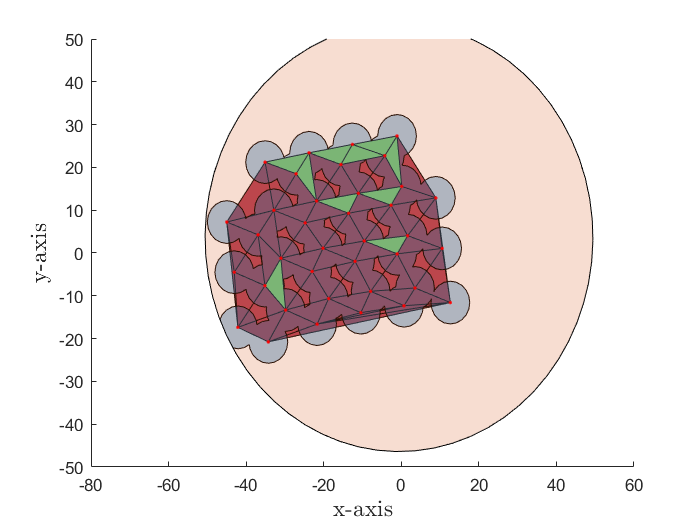

    %clf(900)
    figure(900)
    clf
    hold on
    xlabel('x-axis','interpreter','latex', 'FontSize', 14)
    ylabel('y-axis','interpreter','latex', 'FontSize', 14)
    zlabel('z-axis','interpreter','latex', 'FontSize', 14)
    trisurf(TO_data.ConnectivityList(within_vec_best_pred == 0, :), TO_data.Points(:, 1), TO_data.Points(:, 2), zeros(size(TO_data.Points(:, 2))), 'EdgeColor', [0, 0, 0], 'FaceColor', [0.6350 0.0780 0.1840], 'FaceAlpha', .8) 
    trisurf(TO_data.ConnectivityList(within_vec_best_pred == 1, :), TO_data.Points(:, 1), TO_data.Points(:, 2), zeros(size(TO_data.Points(:, 2))), 'EdgeColor', [0, 0, 0], 'FaceColor', [0.5, 1, 0.3], 'FaceAlpha', .8)
    
    plot(effective_coverage)
    plot(CPshape, 'FaceColor', [0.8500 0.3250 0.0980], 'FaceAlpha', .2)
    %plot(CPshape, 'color', [0.8500 0.3250 0.0980], 'LineWidth', 2)
    plot(newPoint(:, 1), newPoint(:, 2), 'r.', 'MarkerSize', 5)
    %xlim([-50, 50])
    %ylim([-50, 50])

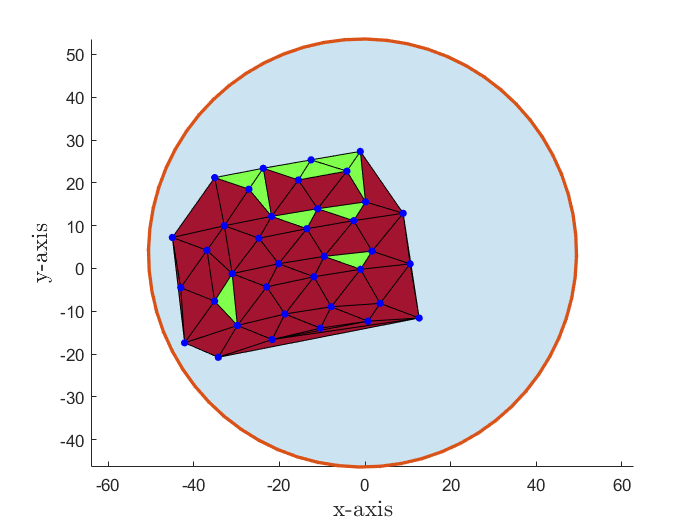


    %axis equal
    
    figure(56)
    clf
    %subplot(2, 1, 1)
    %pbaspect([1 1.2 1])
    hold on
    xlabel('x-axis','interpreter','latex', 'FontSize', 14)
    ylabel('y-axis','interpreter','latex', 'FontSize', 14)
    zlabel('z-axis','interpreter','latex', 'FontSize', 14)
    fill(newCP1(:, 1), newCP1(:, 2), '.-', 'FaceColor', [0 0.4470 0.7410], 'FaceAlpha', .2);
    trisurf(TO_data.ConnectivityList(within_vec_best_pred == 0, :), TO_data.Points(:, 1), TO_data.Points(:, 2), zeros(size(TO_data.Points(:, 2))), 'EdgeColor', [0, 0, 0], 'FaceColor', [0.6350 0.0780 0.1840]) 
    trisurf(TO_data.ConnectivityList(within_vec_best_pred == 1, :), TO_data.Points(:, 1), TO_data.Points(:, 2), zeros(size(TO_data.Points(:, 2))), 'EdgeColor', [0, 0, 0], 'FaceColor', [0.5, 1, 0.3])
    %trisurf(TO_data.ConnectivityList, I_data(:, 1), I_data(:, 2), zeros(size(I_data(:, 3))), 'EdgeColor', [0, 0, 0], 'FaceColor', [0.5, 1, 0.3])
    plot(newCP1(:, 1), newCP1(:, 2), '.-', 'color', [0.8500 0.3250 0.0980], 'LineWidth', 2);
    plot(TO_data.Points(:, 1), TO_data.Points(:, 2), 'b.', 'MarkerSize', 15)
    xlim([-50, 50])
    axis equal

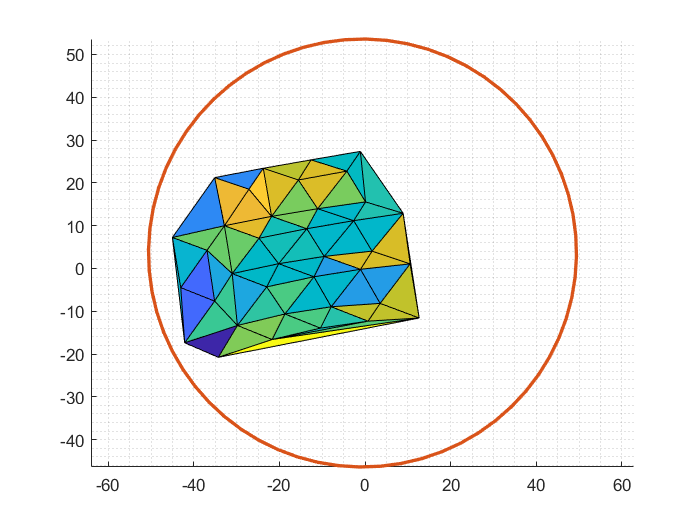

    
    %clf(800)
    figure(800)
    clf
    hold on
    %plot3(I_data(:, 1), I_data(:, 2), I_data(:, 3), 'g.', 'MarkerSize', 15)
    
    %plot3(I(:, 1), I(:, 2), I(:, 3), 'ro', 'MarkerSize', 2)
    %plot3(sparseQ(sparseQ(:, 5) == 32, 1), sparseQ(sparseQ(:, 5) == 32, 2), sparseQ(sparseQ(:, 5) == 32, 3), 'r.', 'MarkerSize', 15)
    tri = delaunay(I_data(:, 1), I_data(:, 2));
    trisurf(tri, I_data(:, 1), I_data(:, 2), I_data(:, 3))
    plot3(newCP1(:, 1), newCP1(:, 2), newCP1(:, 3), '.-', 'color', [0.8500 0.3250 0.0980], 'LineWidth', 2);
    %plot3(CP4(:, 1), CP4(:, 2), CP4(:, 3), '.-', 'color', [0.8500 0.3250 0.0980], 'LineWidth', 2);
    xlim([-50, 50])
    %ylim([-50, 50])
    axis equal
    
    grid minor;

    %axis equal
    %axis equal
    %axis ij
    

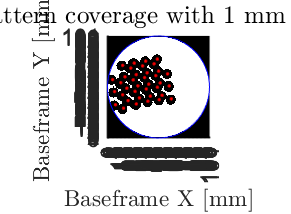

% Rotation to align with base-frame
best_angle_x = 18; % 18.27;
best_angle_y = 0;  % -0.38;
best_angle_z = 0;  % 0.2700;

Rc = createRotationMatrix(best_angle_z, best_angle_y, best_angle_x);
Rc = [Rc, zeros(3, 1); ones(1, 4).*[0, 0, 0, 1]];

T_p2 = [1, 0, 0, p2(1); 0, 1, 0, p2(2); 0, 0, 1, p2(3); 0, 0, 0, 1];
T_base = [1, 0, 0, 0; 0, 1, 0, 0; 0, 0, 1, h_xray; 0, 0, 0, 1];

newCP = zeros(size(CP1, 1), 3);
for k = 1:size(CP1, 1)
    nCP = T_base^-1*T_p2*Rc*T_p2^-1*[CP1(k, 1:3), 1]';
    newCP(k, :) = nCP(1:3);
end
    
    figure(850)
    clf
set(0,'DefaultFigureWindowStyle','docked')
set(gca,'FontSize',14)
set(gca,'LineWidth',1)
set(gcf, 'paperunits', 'centimeters', 'Paperposition', [0 0 20 13]);
set(gcf, 'PaperPositionMode', 'auto')
title('Scan pattern coverage with $1~\mathrm{mm}$ resolution','interpreter','latex', 'FontSize', 15)
xlabel('x-axis','interpreter','latex', 'FontSize', 14)
ylabel('y-axis','interpreter','latex', 'FontSize', 14)
hold on
    n = 100; % 100 mm / 100 cells
    n = n + 1;
    
    grid = zeros(n);
    D = zeros(n, n);
    x0=floor(n/2 + 1);
    y0=floor(n/2 + 1);
    RD=floor(n/2);
    % filter indise circle
    [x,y]=meshgrid(1:n);
    D((x-x0).^2+(y-y0).^2<RD^2)=1;
    area_circ = sum(D, 'all');
    %imshow(flip(D))
    
    for i = 1:size(I_data, 1)
        D((x-(n*(50 + I_data(i, 1))/100)).^2 + (y-(n*(50 + I_data(i, 2))/100)).^2 < (n/20)^2) = 0;
    end
    
    %imagesc(0:n, 0:n, D)
    imagesc((0:n), (0:n), D);          % Plot the image
    colormap(gray);                              % Use a gray colormap
    axis equal                                   % Make axes grid sizes equal
    set(gca, 'XTick', 0:1:(n), 'YTick', 0:(n), ...  % Change some axes properties
             'XLim', [0 n], 'YLim', [0 n], ...
             'GridLineStyle', '-', 'XGrid', 'on', 'YGrid', 'on');
    
    hold on
    % SLI points on surface
    plot(n.*(rad + I_data(:, 1))./(2*rad), n.*(rad + I_data(:, 2))./(2*rad), 'r.', 'MarkerSize', 5, 'LineWidth', 5)
    % Bigger Circle
    plot(n.*(rad + newCP(:, 1))./(2*rad), n.*(rad + newCP(:, 2))./(2*rad), 'b-', 'MarkerSize', 5)
    
    
    
    %imshow(flip(D))
    %truesize([300 200]);
    
    hold on
    grid minor
    xlabel('Baseframe X $\left[\mathrm{mm}\right]$','interpreter','latex', 'FontSize', 14)
    ylabel('Baseframe Y $\left[\mathrm{mm}\right]$','interpreter','latex', 'FontSize', 14)
    zlabel('Baseframe Z $\left[\mathrm{mm}\right]$','interpreter','latex', 'FontSize', 14)


hold on
for n = 1:size(rot_best(1:n_pictures, :), 1)
    vals = I_best(ismember(I_best(:, 5), sortedCoords_ID(1:n)), 1:2);


    canvas = zeros(N, N);
    cen_canvas = floor(N/2 + 1); % center of the circle in the matrix (both x and y)
    Rcanvas = floor(N_survey/2); % radius of the circle in the matrix

    
    [x,y]=meshgrid(1:N);
    canvas((x - cen_canvas).^2 + (y - cen_canvas).^2 < Rcanvas^2) = 1;
    area_circ = sum(canvas, 'all');
    
    for i = 1:size(vals, 1)
        canvas((x - (N*(rad + vals(i, 1))/(2*rad))).^2 + (y - (N*(rad + vals(i, 2))/(2*rad))).^2 < (N/(2*rad/r))^2) = 0;
    end
    
    imagesc((0:N), (0:N), canvas);          % Plot the image
    colormap(gray);                              % Use a gray colormap
    axis equal                                   % Make axes grid sizes equal
    set(gca, 'XTick', 0:1:(N), 'YTick', 0:(N), ...  % Change some axes properties
             'XLim', [0 N], 'YLim', [0 N], ...
             'GridLineStyle', '-', 'XGrid', 'on', 'YGrid', 'on');
    
    hold on
    % SLI points on surface
    plot(N.*(rad + vals(:, 1))./(2*rad), N.*(rad + vals(:, 2))./(2*rad), 'r.', 'MarkerSize', 5, 'LineWidth', 5)
    %Trace path
    plot(N.*(rad + pos_xy(sortedCoords_ID(1:n), 1))./(2*rad), N.*(rad + pos_xy(sortedCoords_ID(1:n), 2))./(2*rad), 'b.-', 'MarkerSize', 15, 'LineWidth', 1.2)
    % Bigger Circle
    plot(N.*(rad + newCP(:, 1))./(2*rad), N.*(rad + newCP(:, 2))./(2*rad), 'b-', 'MarkerSize', 5)
    % Survey Circle
    displacement = mean(N.*(rad + newCP(:, 1:2))./(2*rad)) - mean(N_survey.*(rad_survey + newCP_survey(:, 1:2))./(2*rad_survey));
    plot(displacement(1) + N_survey.*(rad_survey + newCP_survey(:, 1))./(2*rad_survey), displacement(2) + N_survey.*(rad_survey + newCP_survey(:, 2))./(2*rad_survey), 'g-', 'MarkerSize', 5)
    
    drawnow
    frame = getframe;
    im = frame2im(frame);
    [imind,cm] = rgb2ind(im,128);
    if n == 1;
        imwrite(imind,cm,filename,'gif', 'Loopcount',inf);
    else
        imwrite(imind,cm,filename,'gif','WriteMode','append');
    end
    area_dist_sorted(n) = (1 - sum(canvas, 'all')/area_circ) * 100;
end